# **EXERCISE 2 : Build the Simplest WLAN Network**

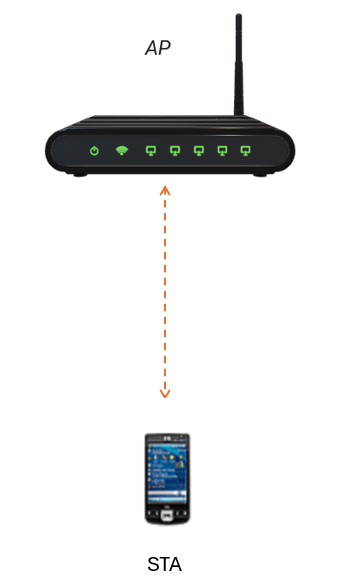

WLAN Network with one AP and one STA 

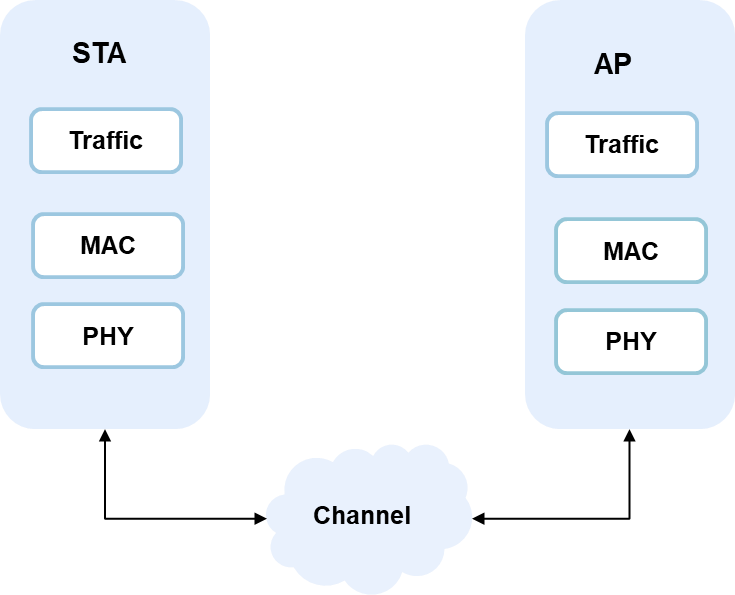

Modeled Blocks 

#### In this exercise, You will learn how to  

- Configure and create WLAN nodes and networks

- Simulate the WLAN network and capture statistics

- Visualize the WLAN and Bluetooth data link layer state transitions

- Analyze WLAN network performance under Bluetooth interference

**Close any previously opened figures and add the path to the Helpers and Utilities directories**

rng("default") 
addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); 
closeFigures();

#### Initialize the wireless network simulator engine

networkSimulator = wirelessNetworkSimulator.init;

### General settings

- `2.4 GHz band`

- `20 MHz wide channel`

- `Channel 7`

- [https://www.mathworks.com/help/releases/R2024b/wlan/gs/wlan-radio-frequency-channels.html](https://www.mathworks.com/help/releases/R2024b/wlan/gs/wlan-radio-frequency-channels.html)

- `Time Unit = 1024us`

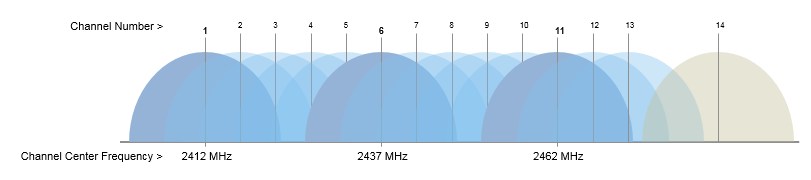

2.4 GHz band contains channels 1 to 13, spaced 5 MHz apart, and channel 14, spaced 12 MHz from channel 13

TU              = 1024e-6; % Time Unit(TU) in WLAN is 1024 us
simulationTime  = 100*TU;  % Simulation time is set to 100*TU
band            = 2.4;
bandwidth       = 20e6;
channel         = 6;
fc              = wlanChannelFrequency(channel,band);

#### Select Interference Modeling Options

- **SOI (Signal of Interest):** The desired signal that the receiver aims to detect or decode.

- **INT (Interference):** Undesired signals from other transmitters or sources that degrade reception quality.

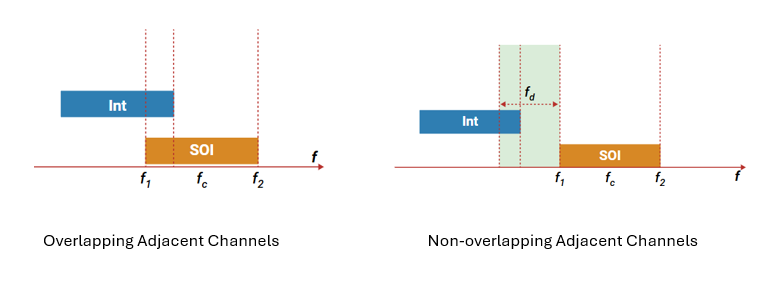

interferenceModeling = "overlapping-adjacent-channel";  
maxInterferenceOffset = 0;

### Geometry

- Define position of AP and STA

% Adjust relative positions of AP and STA to change SNR
AP_pos  = [0,0,0];
STA_pos = [5,5,0];
% Utility function to plot AP, STA, distance and fspl
[dist, atten] = plotNodesPositions(AP_pos,STA_pos,fc);

# Task #1/3 Create a Device Configuration for WLAN AP

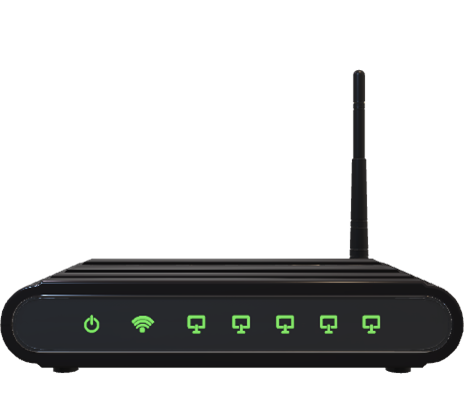

- 802.11n type

- AP is located at [0, 0, 0]

enableAggregation = false;
% Use wlanDeviceConfig() function to configure the AP
% Write configuration in a variable named "APCfg"
% Hint: Type "doc wlanDeviceConfig" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
%    Mode="AP"
%    TransmissionFormat="HT-Mixed"
%    BandAndChannel=[band, channel]
%    ChannelBandwidth= bandwidth
%    AggregateHTMPDU=enableAggregation
%    InterferenceModeling=interferenceModeling
%    MaxInterferenceOffset= maxInterferenceOffset
%    BeaconInterval=10
%    MCS = 6

% <enter code below>
% APCfg = 

macabstraction = false;
phyabstraction = "none";

# Task #2/3 Create a WLAN node with AP Configurations  

Note: All nodes on the network must have same MAC and PHY abstractions  

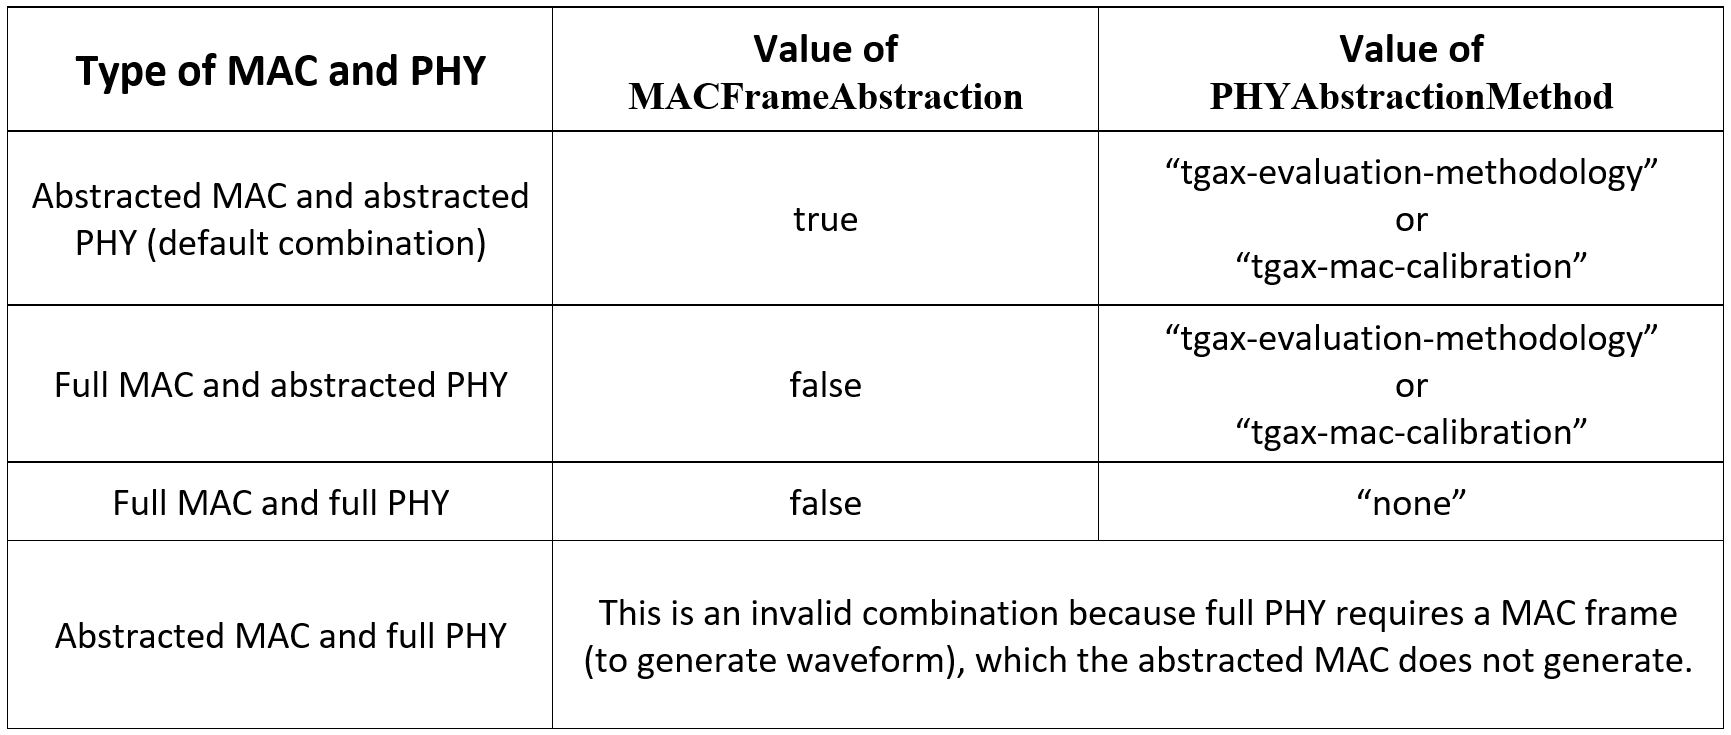

% Use wlanNode() function to instantiate the AP using the configuration you have just created
% Name the variable "AP"
% Note : use the following values to start with
% "DeviceConfig",APCfg
% "Position", AP_pos
% "PHYAbstractionMethod",phyabstraction
% "MACFrameAbstraction",macabstraction
%  Name="AP"

### [Help on creating WLAN node ](https://www.mathworks.com/help/wlan/ref/wlannode.html)

% <enter code below>
% AP = 

### Create the STA

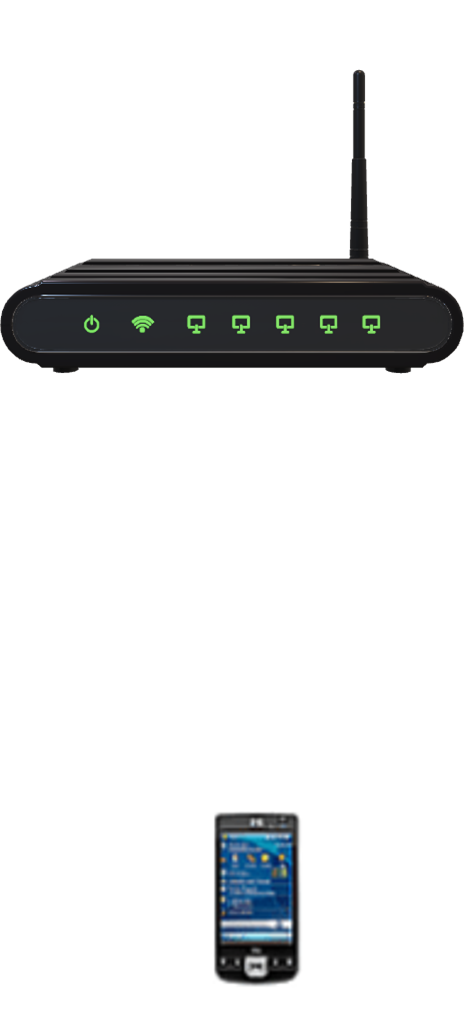

- 802.11n type

- Similar as the creation of the AP

- Code is provided for you

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",0, ... 
    "AggregateHTMPDU",enableAggregation, ...
    "InterferenceModeling",interferenceModeling, ...
    "MaxInterferenceOffset",maxInterferenceOffset ...
    );

STA = wlanNode(...
    "Name","STA",...
    "Position",STA_pos, ...
    "DeviceConfig",STACfg,...    
    "MACFrameAbstraction",macabstraction,...
    "PHYAbstractionMethod",phyabstraction);

# Task #3/3 Associate AP with STA

% Use associateStations() function to define associations between AP's and STA's
% Hint: Click the link below and and see the "Syntax" section.

### [Help on Associating Station ](https://www.mathworks.com/help/wlan/ref/wlannode.associatestations.html)

% Note : use the following values to start with
% AP 
% STA
% Enter code here


#### Add Data Traffic

Application Traffic Pattern Modeling

- FTP (File Transfer Protocol) – Models file-based data transfer sessions.

- On-Off Traffic (Periodic, Bursty, or Random) – Represents intermittent data transmission patterns with varying activity periods.

- Video Streaming – Simulates continuous media flow with variable bit rates.

- Voice over IP (VoIP) – Models real-time voice communication traffic.

- Full-Buffer Traffic – Represents constant data transmission with an always-full buffer.

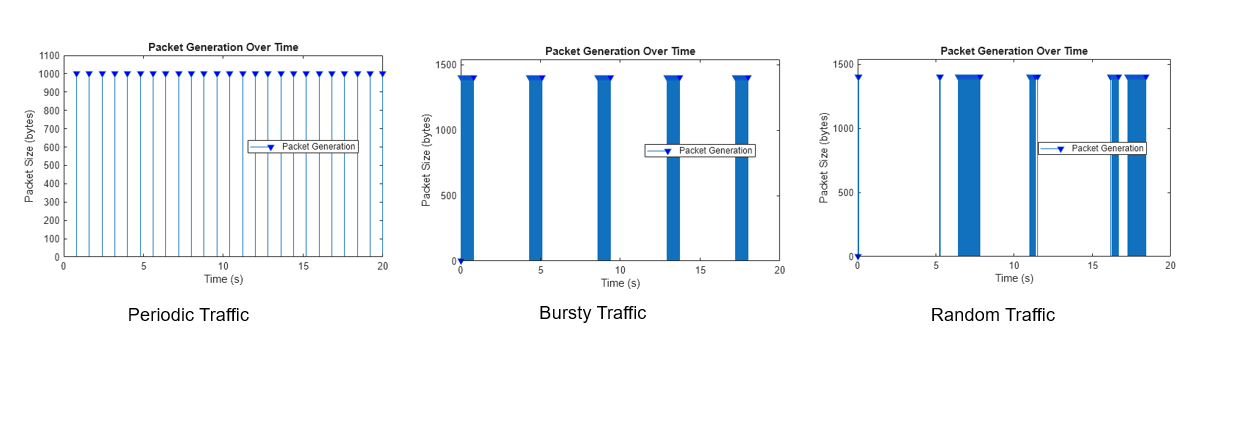

Traffic = "off";
onTime=Inf;
offTime=0;
dataRate=50e3; % in kbps (50 mbps)
packetSize=1500;  % in bytes
if Traffic == "on"
    ap2staTraffic = networkTrafficOnOff(OnTime=onTime,OffTime=offTime,DataRate=dataRate,PacketSize=packetSize);
    addTrafficSource(AP,ap2staTraffic,DestinationNode=STA);
    plotTrafficPattern(simulationTime,ap2staTraffic)
end

#### Introduce **Bluetooth interference** into the simulation to study coexistence effects

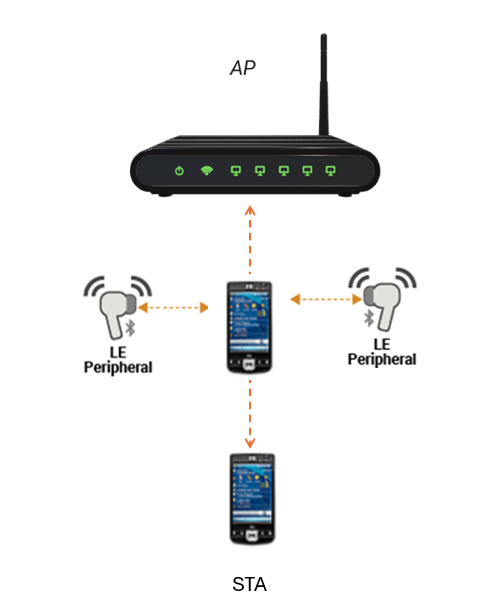

enableBluetoothLEInterference = false;
if enableBluetoothLEInterference
    intBluetoothLENodes = addBluetoothInterference(interferenceModeling,maxInterferenceOffset);
end

#### **Add nodes to the network **

wlanNodes = [AP, STA];
addNodes(networkSimulator,wlanNodes)

**Add Bluetooth nodes to the network **

if enableBluetoothLEInterference 
    addNodes(networkSimulator,intBluetoothLENodes);
end
nodes = networkSimulator.Nodes;

**Enable PCAP capture**

enablePCAPCapture = true;
if enablePCAPCapture
    capturePacketsObj = hExportWLANPackets(wlanNodes, 'pcap', true);
end

#### Enable channel model 

channelModel = "TGAX";
if strcmp(channelModel,"TGAX")
    channel = hSLSTGaxMultiFrequencySystemChannel(nodes);
    addChannelModel(networkSimulator,channel.ChannelFcn);
end

#### Enable packet visualization

enablePacketVisualization = true; 
if enablePacketVisualization
    packetVisObj = hPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=false);
end


**Create node performance visualization object**

perfViewerObj = hPerformanceViewer(wlanNodes,simulationTime);

#### Run the simulation

- WirelessNetworkSimulator is an event-driven simulator

- use the run() method to start the simulation

run (networkSimulator,simulationTime)

APStatistics = statistics(AP,"all");
STAStatistics = statistics(STA);
fprintf('Transmitted Data Frames (AP MAC): %d \n Successfully Transmitted Frames(AP MAC): %d \n Transmitted Request To Send Frames(AP MAC): %d \n Transmitted Beacon Frames(AP MAC): %d \n Received Clear To Send Frames(AP MAC): %d \n Received Acknowledgement Frames(AP MAC): %d \n Received FCS valid Frames(AP MAC): %d \n', ...
    APStatistics.MAC.TransmittedDataFrames, ...
    APStatistics.MAC.SuccessfulDataTransmissions, ...
    APStatistics.MAC.TransmittedRTSFrames, ...
    APStatistics.MAC.TransmittedBeaconFrames, ...
    APStatistics.MAC.ReceivedCTSFrames, ...
    APStatistics.MAC.ReceivedAckFrames, ...
    APStatistics.MAC.ReceivedFCSValidFrames);
fprintf('Transmitted Data Frames (AP PHY): %d \n', APStatistics.PHY.TransmittedPackets);
fprintf('Transmitted Data Frames (STA PHY): %d \n', STAStatistics.PHY.TransmittedPackets);
fprintf('Received Data Frames(STA MAC): %d \n Received Beacon Frames(STA MAC): %d \n Transmitted Clear To Send Frames(STA MAC): %d \n Transmitted Acknowledgement Frames(STA MAC): %d \n Received FCS valid Frames(STA MAC): %d \n', ...
    STAStatistics.MAC.ReceivedDataFrames, ...
    STAStatistics.MAC.ReceivedBeaconFrames, ...
    STAStatistics.MAC.TransmittedCTSFrames, ...
    STAStatistics.MAC.TransmittedAckFrames, ...
    STAStatistics.MAC.ReceivedFCSValidFrames);

#### Calculate throughput, packet loss ratio,latency at nodes 

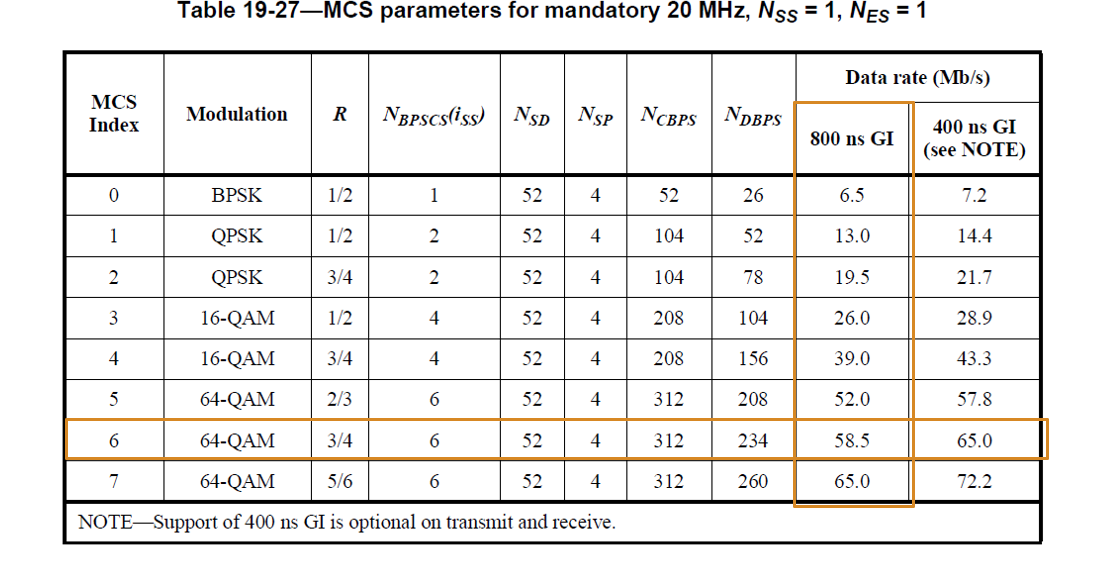

% Calculate throughput (Mbps) at Nodes
throughputs = throughput(perfViewerObj,[wlanNodes(:).ID])

% Release PCAP capture object
if enablePCAPCapture
    delete(capturePacketsObj.PCAPObjList);
end

#### Copyright 2024-2025 The MathWorks, Inc